## Wireless Networking Project (2026) -- Part 1

As described in `WirelessProjectPreview.mlx`, the MATLAB source code file called *WirelessNetwork.m* includes all the functionality needed for the Wireless Networking semester project.  The code is written in an object-oriented fashion, which is explained in this Notebook.  The code allows you to place base stations, allocate channels and power to the base stations, optionally use *sectorized *antennas, and analyze the performance (e.g., computing SINR at the locations of the mobile handsets in your network).  By using this object, you will be able to design your network and analyze its performance. 

This Notebook should be run in MATLAB using *Live Edito*r.  For each section click "Run Section" to run all the code in the section you are in.  The output will be shown in a window to the right.  After running to code, click on the code to highlight the corresponding output.  Alternatively, you can click "Step" and just the next line of code will be run.  Note that not every line of code produces output.

# Creating a WirelessNetwork Object

To begin, you need to construct a WirelessNetwork object.  An object is both a data structure (containing *properties*) and a set of functions (called *methods)* that interact with the data structure. 

Let's give the object that we create the name "`net`".  To create a WirelessNetwork object and assign it to `net`, type the following:

net = WirelessNetwork;

This constructs an object called `net` of class `WirelessNetwork`.  By typing "`net`", you can see that its properties are initially either empty or set to a default:

net

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: []
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


 By typing "`methods(net)`" you can see a list of methods associated with the object:

methods(net) 

Methods for class WirelessNetwork:

AddBase               AnalyzeNetwork        ComputeCost           ComputeSINR           CreateCentralCluster  CreateCluster         CreateFirstTier       FindChannel           FindMaxUsers          FindPower             Load                  MapCity               MapCoverage           MapMobiles            MapSINR               RemoveBase            Save                  Sectorize             SetChannels           SetPower              WirelessNetwork       

Methods of WirelessNetwork inherited from handle.



You can get help on any of the methods by typing the name of the object followed by a period and the name of the method.  For example, type "`help WirelessNetwork.CreateFirstTie`r" to get help on the CreateTiers method:

help WirelessNetwork.ComputeSINR

  method ComputeSINR computes the SINR of mobiles at locations "ms_locations"
  usage: SINRdB = obj.ComputeSINR( ms_locations, [pl_exponent], [channel] )
         ms_locations = row vector containing the locations of the mobiles (as complex numbers) 
         [pl_exponent] = path loss exponent (optional)
         [channel] = row vector containing the channel set to use for each mobile (optional)



Optional arguments appear in square brackets.

# Managing Channels

Your `WirelessNetwork` object needs to contain a property called "`channel_sets`" which groups the channels that you've purchased into sets. Later, when you create base stations, you need to assign a particular channel set to each base station.  

As the term *channels* is a bit ambiguous, here we will use the terms *RF channels* and *traffic channels*.  An RF channel occupies a fixed amount of bandwidth (like 5 MHz), and each RF channel supports multiple traffic channels through the use of OFDM (orthogonal frequency division multiplexing).  In the literature and in standards, traffic channels are also sometimes called *logical *channels or* transport* channels depending on which network layer you are viewing it from.  In this project, each RF channel supports 10 traffic channels.  Meanwhile, a traffic (or logical) channel can provide service to 1 user.  So, for instance, a single RF channel can allow 10 users to simultanouesly make voice calls since each one of those users would need 1 logical channel for service.   As described later, you will be able to *purchase *a number of RF channels, and this cost will factor into the total cost of your network. (Note -- technically, the FCC does not sell channels, but rather grants licenses as the result of a frequency spectrum auction, so later will characterize this as *purchasing a spectrum license*.)

For example, suppose you want to design your network using *clusters* that contain N=4 cells per cluster.  Thus, you will need to have 4 distinct sets of frequencies, one set for each cell in each cluster.  However, you might want to purchase more than just 4 RF channels so that you can assign multiple channels to each cell.  Suppose that you have purchased 10 RF channels.  Each of your clusters can have 2 cells that are assigned 3 channels and 2 cells that are assigned 2 channels (since 2*3+2*2 = 10).   

For this example, you can set up your channel_sets as follows:

net.channel_sets = [3 3 2 2]

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: [3 3 2 2]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


In this example, if you assign the first or second channel set to a base station, then it will have 3 channels to use to reach the mobiles in its cell.  Since each RF channel suports 10 logical channels, this means the base station can simultaneously support up to 30 users.   If you assign the third or fourth channel set to a base station, then it will have 2 channels to use (i.e., 20 users at a time). The process you will need to use to assign channel sets to base stations is explained in the next section.

As a sanity check, you need to make sure that the total number of channels used equals the number of channels you have purchased:

total_channels = sum(net.channel_sets)

total_channels = 10

# Adding Base Stations

You can add a base station by using the `AddBase` method.  When adding a base station, you will have to specify its location, which channel set it will use, and its transmit power.  For convenience, locations are specified using *complex* numbers: The real part specifies the east-west coordinate, while the imaginary part specifies the north-south coordinate.   

To get help on the AddBase method, type:

help WirelessNetwork.AddBase

  method AddBase adds one (or more) base station(s)
  usage obj.AddBase( location, channels, power_dBm   )
        location = location(s) of the new base station(s)
        channels = channel set used by the sectors of the new base station(s)
        power_dBm = power used by the sector(s) of the new base stations(s), in dBm



Let's add our first base station.  We will put it at location 1.5 (representing a location 1.5 units to the east of the origin), assign it to use channel set 1 (containing 3 channels as described above), and assign a transmit power level of 30 dBm.

net.AddBase( 1.5, 1, 30 );

Now, let's add three more base stations.  We will put the second one at location -1.5 (i.e., 1.5 units to the west of the origin).  For the third and fourth locations, we will use imaginary values to indicate that they lie north and south of the origin (in MATLAB, you can use "1i" to indicate the imaginary number).  For each of these base stations, we will assign a different channel set.  We will keep the powers all equal to 30 dBm.  The `AddBase` method allows you to add multiple base stations with a single call by specyifing a column vector for each entry.  For instance, to add three base stations with one call of `AddBase`:

net.AddBase( [-1.5 1i/sqrt(3) -1i/sqrt(3)]', [2 3 4]', [30 30 30]' );

The transpose operator (') is required to convert the row vectors into a column vector.  The reason why we picked these locations is to make the cells arranged in a hexagonal grid, since 2/sqrt(3) is the height of a hexagon when its radius is unity (R=1).  

Upon placing these 4 base stations, you will notice that three properties of the object have changed: `bs_locations`, `bs_channels`, and` bs_power_dBm:`

net.bs_locations

ans =    1.5000 + 0.0000i
  -1.5000 + 0.0000i
   0.0000 - 0.5774i
   0.0000 + 0.5774i


net.bs_channels

ans =      1
     2
     3
     4


net.bs_power_dBm

ans =     30
    30
    30
    30


# Removing Base Stations

After base stations are added, you may remove any of them using the RemoveBase method.

help WirelessNetwork.RemoveBase

  method RemoveBase removes one (or more) base station(s)
  usage obj.RemoveBase( bs_to_remove )
        bs_to_remove = list of the indices of the base stations to remove



As an example, let's remove the last base station that we just added:

net.RemoveBase(4)

To confirm that it is gone:

net.bs_locations

ans =    1.5000 + 0.0000i
  -1.5000 + 0.0000i
   0.0000 - 0.5774i


net.bs_channels

ans =      1
     2
     3


net.bs_power_dBm

ans =     30
    30
    30


Before proceeding, we should add it back:

net.AddBase( -1i/sqrt(3), 4, 30 );

# Creating a Cluster

The network that we have created contains 4 base stations that are arranged in a hexagonal configuration.  Since we are assigning a different channel set to each base station, we have a *cluster *with N=4.  To make it easy for you to create clusters, there is a method called `CreateCentralCluster` that can create a cluster with a single command.

help WirelessNetwork.CreateCentralCluster

  method CreateCentralCluster creates a cluster of N cells centered at location "center"
  usage: obj.CreateCluster( N, center )
         N = cluster size: number of cell/cluster (can be between 1 and 7, inclusive)
         center = center of the cluster



 To use the method, you need to specify the value of N and the location of the center of the cluster:

net.CreateCentralCluster( 4, 0 )

ans =   WirelessNetwork with properties:

           bs_locations: [4×1 double]
            bs_channels: [4×1 double]
           bs_power_dBm: [4×1 double]
           channel_sets: [3 3 2 2]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


Note that the value of N must be 1, 3, 4, or 7.  Other values are not supported.

The network that has been created by this single command is identical to the one we created by adding 4 base stations with the `AddBase` method.  However, when the command is used, the powers of the base stations are all set to a default value of 0 dBm.  

net.bs_power_dBm

ans =      0
     0
     0
     0


These powers may be adjusted according to instructions given below.

# Mapping Coverage

Now that we've placed some base stations, we can plot a coverage map by using the `MapCoverage` method.  

help WirelessNetwork.MapCoverage

  method MapCoverage shows a coverage map for a cellular wireless network.
 
  usage: obj.MapCoverage( [pl_exponent], [w e s n] )
         [pl_exponent] = path loss exponent (optional argument)  
         [w e s n] = coorinates bounding the map (optional argument)



The arguments pl_exponent and [w e s n] are optional and described below.   

The coverage map is created by typing:

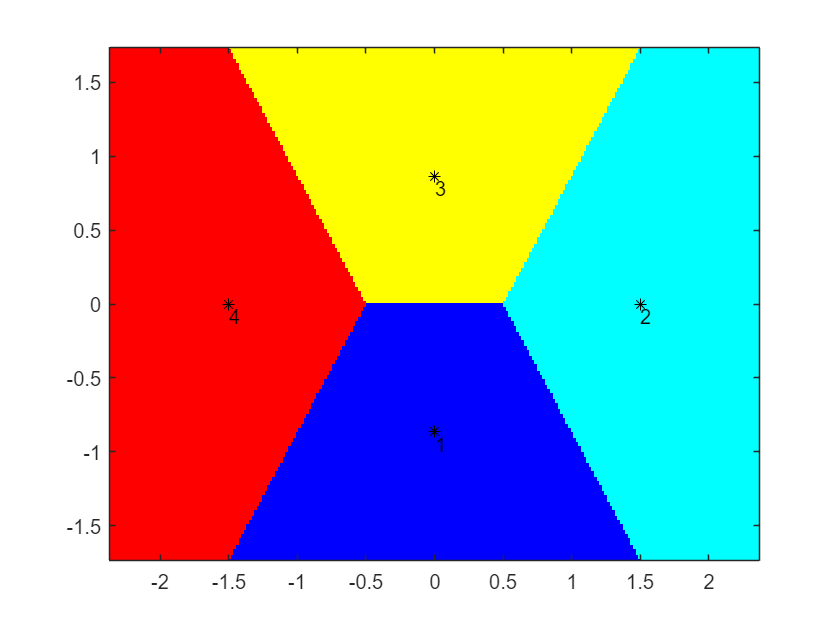

net.MapCoverage

The map shows an asterisks at the location of each base station, and places the number of the base station next to it.  The footprint of each cell is shown with a colored region.  Cells of the same color use the same channels; i.e., they are co-channel cells.  At this point, each of the four cells has its own distinct channel set, which is why each color is used just once.  For this network, there will be no interference since frequencies are not reused.

# Creating a Tier of Interfering Cells

Our network of N=4 cells is not very interesting because it has no interference (since each channel set is used by only one cell).  To consider the effects of interference, we could place a tier of interfering clusters around the cluster we have already created.  Because we are using hexagonal cells, there will be 6 clusters surrounding the central cluster, for a total of 4*6 = 24 more base stations, bringing the total number of base stations up to 28.  While we could place each one of these cells independently by using the `AddBase` method, or each cluster by using `CreateCentralCluster` method, there is a method called `CreateFirstTier` that will create the entire network of interest -- namely, a central cluster of N cells plus the surrounding first *tier* of interferers. 

help WirelessNetwork.CreateFirstTier

  method CreateFirstTier creates a network of hexagonal cells
  containing a central cluster and one tier of interfering
  clusters.  The total number of clusters created is 7.
  N cells
  usage: obj.CreateTiers( N )
         N = cluster size (can be 1, 3, 4, or 7)



The only argument is N, which is the cluster size. Sticking to our example of N=4 we can create the network:

net.CreateFirstTier(4)

ans =   WirelessNetwork with properties:

           bs_locations: [28×1 double]
            bs_channels: [28×1 double]
           bs_power_dBm: [28×1 double]
           channel_sets: [3 3 2 2]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


Notice that `bs_locations`, `bs_channels`, and `bs_power_dBm `are all column vectors of length 28, since there is one entry in each of these per base station. As with `CreateCentralCluster`, note that `bs_power_dBm `is reset so that all cells transmit with power 0 dBm:

net.bs_power_dBm

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Now that we've created a larger network containing a first tier of interfering clusters, let's map its coverage:

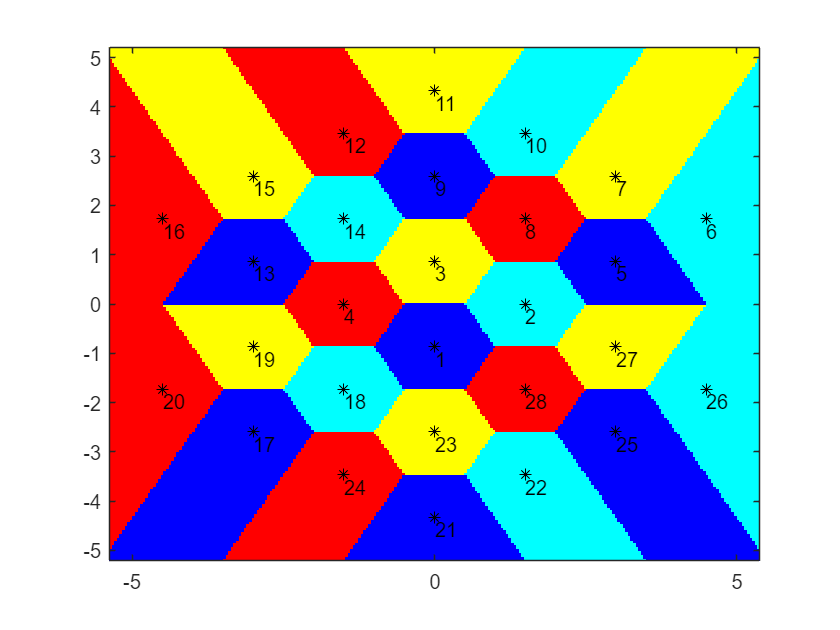

net.MapCoverage

Notice how each color appears 7 times -- once for the central cluster and once for each of the interfering cells in the tier of interfering clusters.  The honeycomb appearance of the hexagonal grid is starting to show, though the cells on the outer edges are not complete hexagons because there is not another tier of interferers to impose outer boundaries.

# Changing the Path-Loss Exponent

When no arguments are given to it, the `MapCoverage` method uses the current value of the `pl_exponent` property, which is set to a default value of $$\alpha=3$$ at the time the object is constructed.  The path-loss exponent can be changed one of two ways.  The first is to directly edit the property:

net.pl_exponent = 3.5

net =   WirelessNetwork with properties:

           bs_locations: [28×1 double]
            bs_channels: [28×1 double]
           bs_power_dBm: [28×1 double]
           channel_sets: [3 3 2 2]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3.5000
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


The second way is to enter the path-loss exponent as the first argument of the `MapCoverage` method:

net.MapCoverage( 3.5 )

This *temporarily *changes the value of the `pl_exponent` property before plotting the coverage map.

Before continuing, let's restore the value of` pl_exponent` to its default value:

net.pl_exponent = 3;

# Changing Map Resolution

The `map_resolution` property specifies the *resolution* of the map.  By default, it is set to 250, which means that the map is created by plotting a grid of 250 by 250 points (essentially pixels).  To change the resolution, simply change the property:

net.map_resolution = 750

net =   WirelessNetwork with properties:

           bs_locations: [28×1 double]
            bs_channels: [28×1 double]
           bs_power_dBm: [28×1 double]
           channel_sets: [3 3 2 2]
    sector_offset_angle: 0
         map_resolution: 750
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


Running `MapCoverage` again will create a map with a higher resolution: 

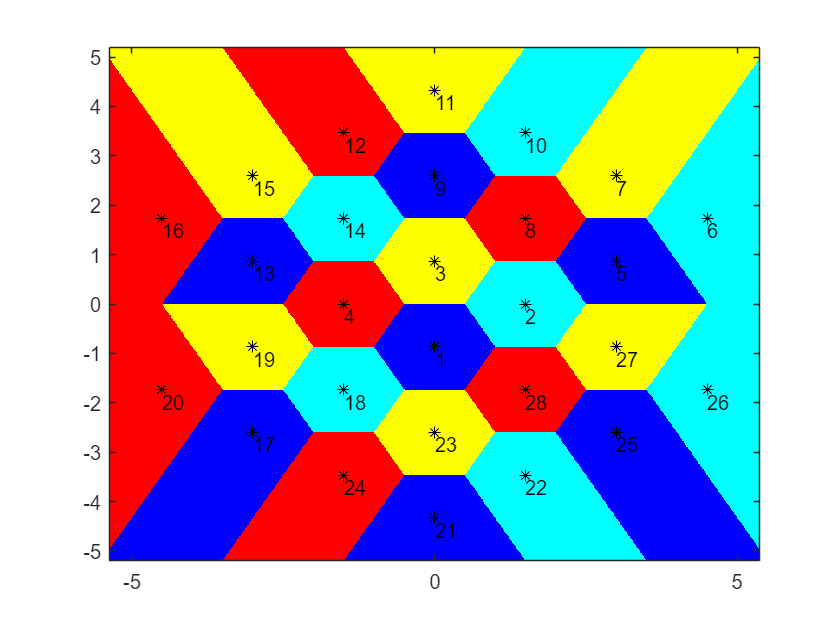

net.MapCoverage

Notice that the edges of the hexagons are now smoother, though it took longer for your computer to generate the map.  Now that this property has been changed, `net.MapCoverage` will continue to use this value until it is changed again.

Since `map_resolution` impacts the time it takes to create the map, you may want to use a smaller value while working on intermediate results, but then set it to a higher value prior to creating your final coverage map.

# Bounding the Map

By default, the coverage map is bounded by a small border around the outermost base stations.  To force the range of the map to be limited to a certain range, set the second argument of the `MapCoverage` method:

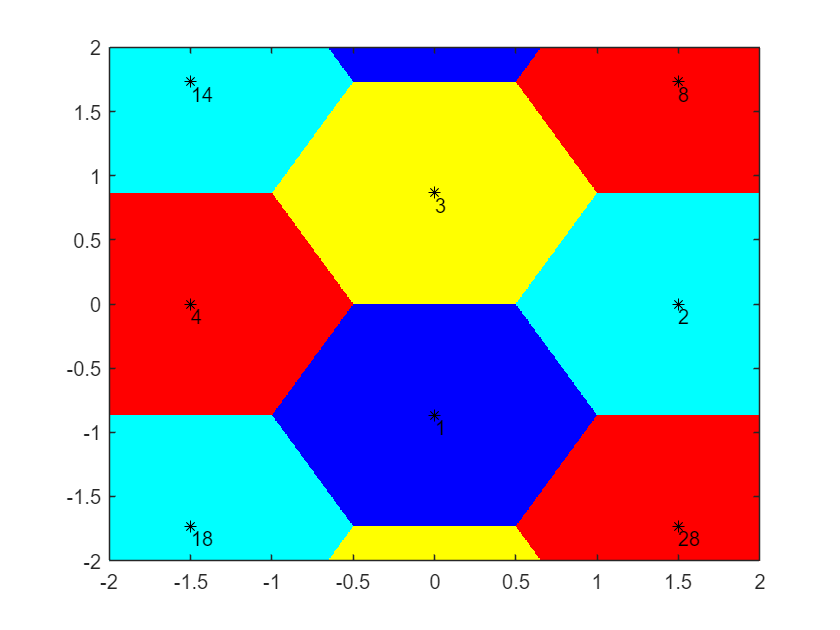

net.MapCoverage( 3, [-2 2 -2 2] )

The second argument is a four-element vector specifying the western, eastern, southern, and northern boundaries of the plot, respectively.

# Computing SIR

The `ComputeSINR` method computes the signal-to-noise-and-interference ratio (SINR) at every location specified in its first input argument.  

help WirelessNetwork.ComputeSINR

  method ComputeSINR computes the SINR of mobiles at locations "ms_locations"
  usage: SINRdB = obj.ComputeSINR( ms_locations, [pl_exponent], [channel] )
         ms_locations = row vector containing the locations of the mobiles (as complex numbers) 
         [pl_exponent] = path loss exponent (optional)
         [channel] = row vector containing the channel set to use for each mobile (optional)



To compute the signal-to-interference ratio (SIR) rather than the SINR, we need to turn the noise off (since its default value is -100 dBm).  This is accomplished by setting the `noise_dBm` proprty to `-Inf` (negative infinity, which corresponds to a noise power of 0 mW):

net.noise_dBm = -Inf;

Now that the noise is off, we can compute the SIR by calling the `ComputeSINR` method.  However, the method needs to know *where *we want to measure the SIR.   This is achieved by setting the first argument of the method to a vector containing all the locations for which we want to measure the SIR.  Let's call this vector `ms_locations` (i.e., the locations of our mobile stations), and we will set the vector to equal the locations of the six corners of the central cell.

H = sqrt(3);
ms_locations = [ +0.5 1-H*1i/2 +0.5-H*1i -0.5-H*1i -1-H*1i/2 -0.5];

Let's see where these mobiles are -- this indicates their locations with a black 'x'

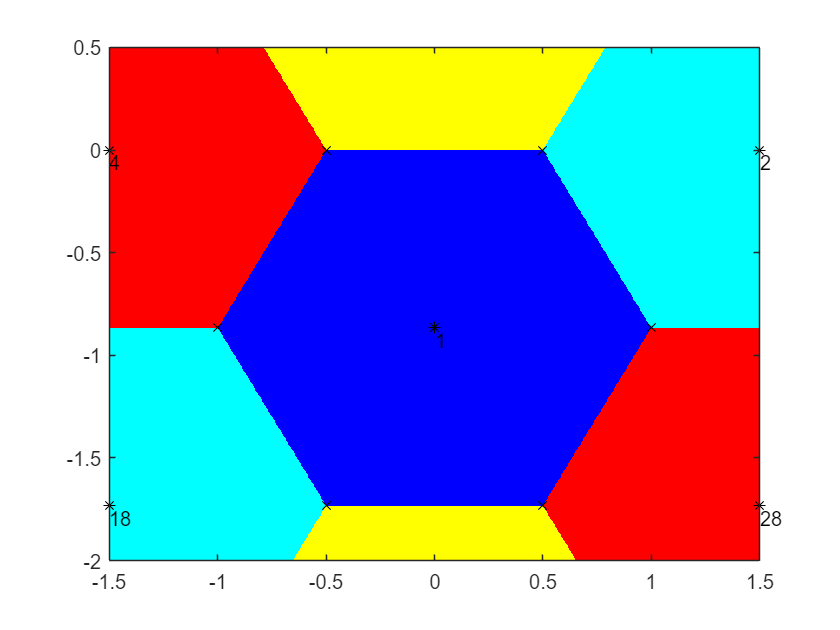

 net.MapCoverage( 3, [-1.5 1.5 -2 0.5] );
 hold on;
 plot( ms_locations, 'kx' );
 hold off;

Having set the locations to measure the SIR, we can call the method:

net.ComputeSINR( ms_locations )

ans =     7.5744    7.5744    7.5744    7.5744    7.5744    7.5744


The SIR values that are computed are all in dB.  Compare this against what you got in homework #3 problem 3(b).

The second argument is the path-loss exponent (recall that it is optional, and that if it is not given as an argument, then the current value of `pl_exponent` is used).   Now, let's find the SIR when there is a different path-loss exponent:

net.ComputeSINR( ms_locations, 4 )

ans =    12.3515   12.3515   12.3515   12.3515   12.3515   12.3515


# Computing SINR

Now let's consider the impact of noise.  Turn the noise back on by setting it to a finite value:

net.noise_dBm = -30;

Now compute the SINR

net.ComputeSINR( ms_locations )

ans =     6.9291    6.9291    6.9291    6.9291    6.9291    6.9291


Notice that including the noise causes the ratio to decrease, as we would expect.  Here, we had to use a relatively large value for `noise_dBm` because the signals are not transmitting over long distances and therefore are received with a high power.

# Mapping SINR

The `MapSINR` method provides a map showing regions where the SINR is good and regions where it is bad.

help WirelessNetwork.MapSINR

  method MapSINR shows an SINR map for a cellular wireless network.
 
  usage: obj.MapSINR( [pl_exponent], [w e s n], [thresh] )
         [pl_exponent] = path loss exponent (optional argument)  
         [w e s n] = coordinates bounding the map (optional argument)  
         [thresh]    = SINR threshold



The first two arguments are the same as that of the `MapCoverage` method and are optional.  The third argument, which is optional, is a threshold.   Let's run it without any arguments:

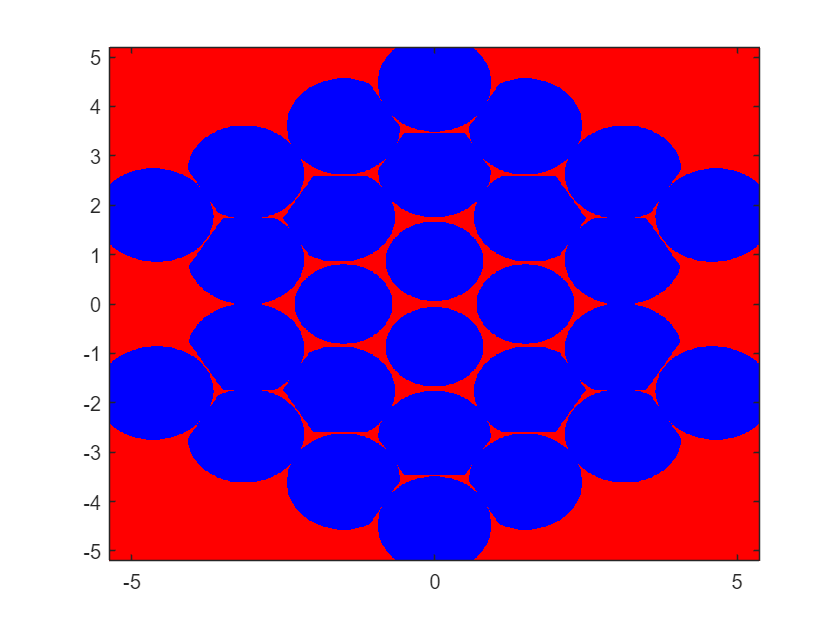

Covering 63.95 percent of the area with sufficient SINR
worst case SINR is -3.045933


net.MapSINR

`MapSINR `shows the regions of the coverage map for which the SINR is above the threshold (indicated in blue) and regions where it is below the threshold (indicated by red).  The implication of the threshold is that it is the minimum SINR to have reliable coverage, so mobiles in the blue areas will be *covered,* while mobiles in the red areas will not.

If the third argument (thresh) is not specified, then the function will use the value of the `SINR_thresh`, which has a default value of 10 dB when the object is created.

net.SINR_thresh

ans = 10

We can improve the SINR map slightly by turning off the noise, which will increase the SINR everywhere:

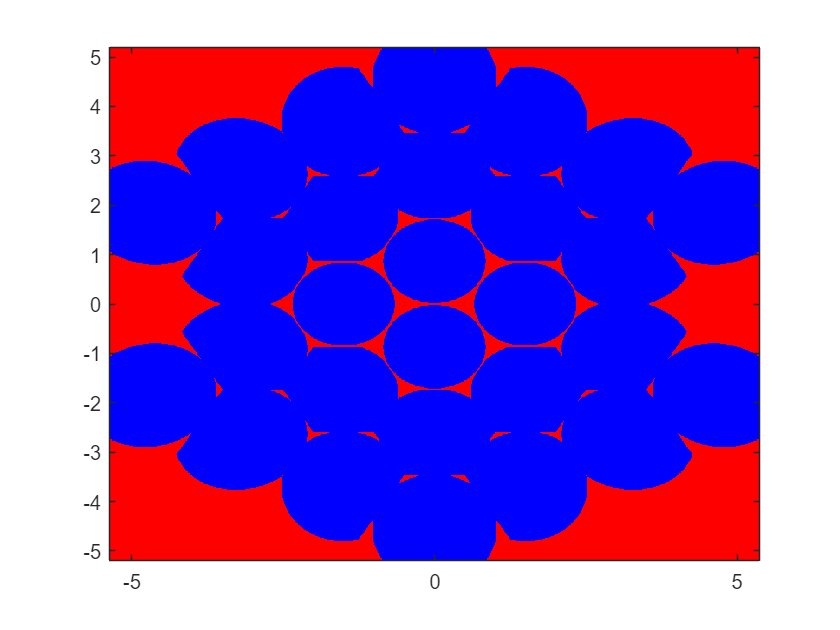

Covering 70.90 percent of the area with sufficient SINR
worst case SINR is -1.274930


net.noise_dBm = -Inf;
net.MapSINR

Notice that the coverage has improved slightly (i.e., the fraction of the area that is blue has increased from 63.95% to 70.90%).  Now let's generate a map using a smaller threshold (5 dB):

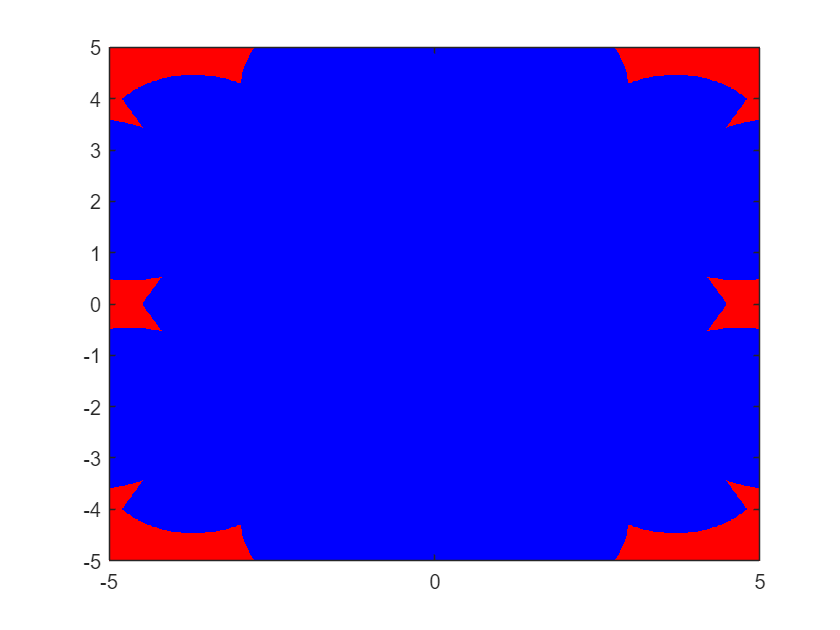

Covering 92.37 percent of the area with sufficient SINR
worst case SINR is -1.275584


net.MapSINR(3,[-5 5 -5 5], 5)

With this lower threshold, a much larger portion of the map is covered -- 92.37%.

# Changing Base Station Power

By default, the network is created such that every base station transmits at the same power, namely 0 dBm.  The power can be modified by editing the `bs_power_dBm` property, or by using the `SetPower` method:

help WirelessNetwork.SetPower

  method SetPower sets the power of each sector
  usage obj.SetPower( bs_power_dBm )
        bs_power_dBm = a num_sectors by num_bs matrix containing the power of the sectors (in dBm)



For instance, let's use this function to *randomly* set the power of each base station to some value between 0 and 10 dBm:

bs_power_dBm = 10*rand(28,1);
net.SetPower( bs_power_dBm );

Now let's map the coverage:

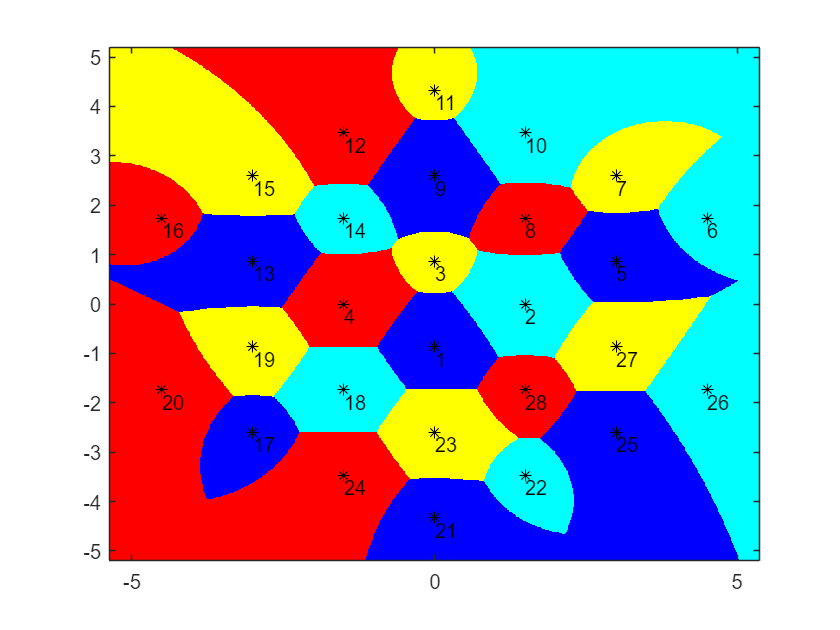

net.MapCoverage

Notice that when the powers are unequal, the cells no longer look like hexagons.

Before continuing, let's restore the power to its previous value:

bs_power_dBm = zeros(28,1);
net.SetPower( bs_power_dBm );

# Determing the Cost of Your Network

The cost of your network can be counted using the `ComputeCost` method

help WirelessNetwork.ComputeCost

  method ComputeCost computes the cost (in thousands of dollars) of the network
  usage cost = obj.ComputeCost



The cost for each base station is $250,000 plus $25,000 for each RF channel used at that base station.  The $250K for the base station is mean to cover the cost of the antenna structure, land it is on, and backhaul to connect to the Internet, while the $25K per channel is meant to cover the incremental cost of the RF equipment.  For instance, if the base station is assigned a channel set containing 3 channels, then the cost of that base station is $325,000.

Additionally, you will need to incorporate the cost of purchasing your spectrum license, which comes at the cost of $500,000 for each channel used by the network.

Call `ComputeCost` to determine the cost:

net.ComputeCost

ans = 13750

The cost is in thousands of dollars, so "13750" should be interpreted as $13,750,000.

Once the function is called, the `cost` property of the `net` object is updated to reflect the cost:

net.cost

ans = 13750

# Saving and Loading Networks

You can save the design by calling the `Save` method: 

help WirelessNetwork.Save

  method Save saves the network design to a file
  usage obj.Save( [save_filename] )
        [save_filename] = name of the file (in single quotes)



without an argument, the name stored in the `save_filename` property is used, which defaults to the filename ``MyProject.mat''.

net.Save

Alternatively, you can specify the name of the file with an argument, like `net.Save( 'Example' )`

The converse to saving is loading

help WirelessNetwork.Load

  method Load loads the network design from a file
  usage obj.Load( [save_filename] )
        [save_filename] = name of the file (in single quotes)



net.Load

Again, the argument is optional and if not used will use the value in the `save_filename` property.

# Another Example: N=7

Now lets create a network with cluster size N=7.  We will begin by creating a new net object and then using the CreateFirstTier function, being sure to set the argument to 7:

net = WirelessNetwork;
net.CreateFirstTier(7)

ans =   WirelessNetwork with properties:

           bs_locations: [49×1 double]
            bs_channels: [49×1 double]
           bs_power_dBm: [49×1 double]
           channel_sets: []
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


We can now visualize it by calling `MapCoverage:`

net.MapCoverage

Now, lets' place mobiles at the corners of the central cell so that we can compute the SIR at those locations:

H = sqrt(3);
ms_locations = [ +0.5 1-H*1i/2 +0.5-H*1i -0.5-H*1i -1-H*1i/2 -0.5]+0.5*H*1i;

Let's see where these mobiles are -- this indicates their locations with a black 'x'

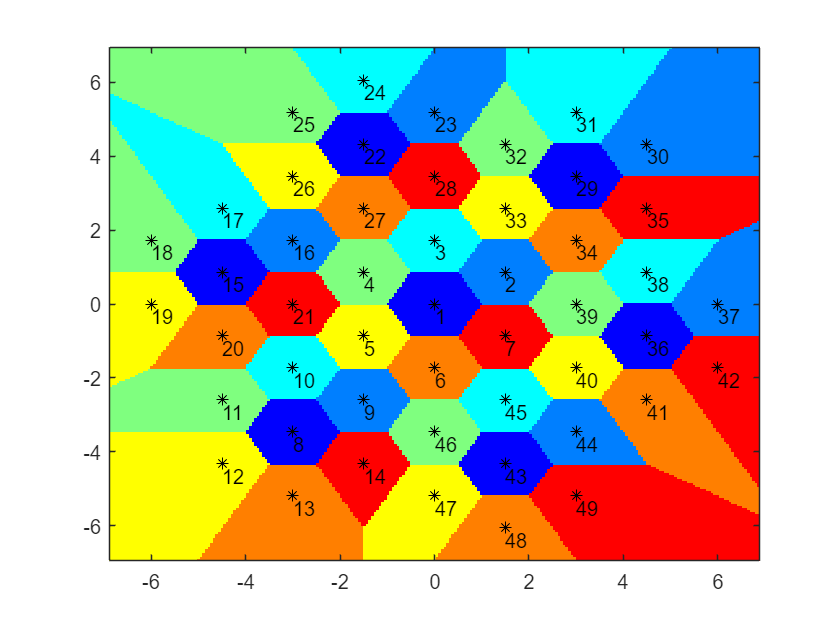

 net.MapCoverage( 3, [-1.5 1.5 -1.5 1.5] );

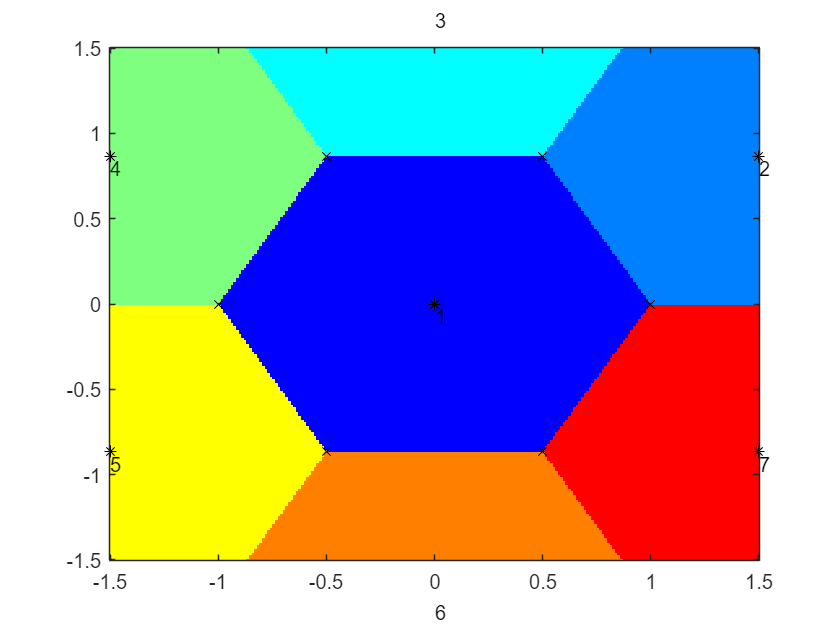

 hold on;
 plot( ms_locations, 'kx' );
 hold off;

Then, to find the SIR at these locations, force the noise to -Inf dBm and call the `ComputeSINR `method:

net.noise_dBm = -Inf;
net.ComputeSINR( ms_locations )

ans =    11.5753   11.5753   11.5753   11.5753   11.5753   11.5753


The above was found for $$\alpha=3$$, but we can also find it for a different path loss exponent:

net.ComputeSINR( ms_locations, 4 )

ans =    17.8226   17.8226   17.8226   17.8226   17.8226   17.8226


How does this compare against the values that were found in the corresponding lecture?

Now that you are done with Part 1 of this tutorial, please proceed to Part 2.